clear;
% close all;
clc;
load('test_data2.mat');
img_bin = img;
load('ssss.mat');
% img_bin = ImgMask;


VolumeThs = 25;
stats = regionprops3(img_bin,'Volume','VoxelIdxList');
NumConct = length(stats.Volume);
LenVoxel = stats.Volume;
IndVoxel = stats.VoxelIdxList;
NumConctUpd = 0;
IndVoxelUpd = {};
LenVoxelUpd = zeros();
%用于查询连通域的划分
DictImg = zeros(size(img_bin));
for i = 1:NumConct
    if(LenVoxel(i,1) < VolumeThs)
        img_bin(IndVoxel{i}) = 0;
        continue;
    end
    NumConctUpd = NumConctUpd + 1;
    IndVoxelUpd{NumConctUpd} = IndVoxel{i};
    LenVoxelUpd(NumConctUpd,1) = LenVoxel(i,1);
    DictImg(IndVoxelUpd{NumConctUpd}) = NumConctUpd;
end

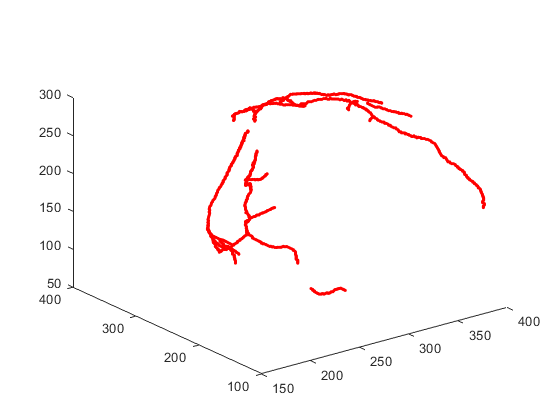

[cpt_x, cpt_y, cpt_z] = ind2sub(size(DictImg), find(DictImg));
plot3(cpt_x, cpt_y, cpt_z, '.r');

BranchPoint = find(bwmorph3(DictImg, 'branchpoints'));
EndPoint = find(bwmorph3(DictImg, 'endpoints'));

Nodes = [BranchPoint;EndPoint];
Trees = Prim(Nodes,DictImg);

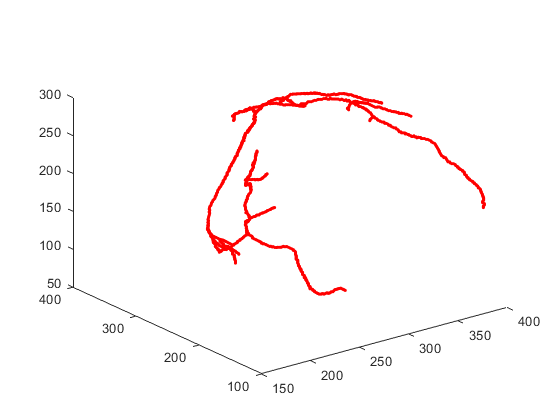

%连线
SrcNodes = Nodes(Trees(:,1));
DstNodes = Nodes(Trees(:,2));
[XSrc,YSrc,ZSrc] = ind2sub(size(DictImg),SrcNodes(:,1));
[XDst,YDst,ZDst] = ind2sub(size(DictImg),DstNodes(:,1));
Dxyz = -[XSrc-XDst,YSrc-YDst,ZSrc-ZDst];
r = (((Dxyz(:,1)).^2 + (Dxyz(:,2)).^2 + (Dxyz(:,3)).^2)).^(0.5);
CosTheta = ((Dxyz(:,1)).^2+(Dxyz(:,2)).^2).^(0.5) ./ r(:,1);
SinTheta = (Dxyz(:,3)) ./ r(:,1);
CosBeta = (Dxyz(:,1)) ./ (((Dxyz(:,1)).^2 + (Dxyz(:,2)).^2).^(0.5));
SinBeta = (Dxyz(:,2)) ./ (((Dxyz(:,1)).^2 + (Dxyz(:,2)).^2).^(0.5));
for i = 1:length(Trees)
    if Trees(i,3) == 0 || Trees(i,3) > 50
        continue;
    end
    r1 = floor(r);
    for j = 1:r1(i,1)
        Dz = floor(j * 1 * SinTheta(i,1));
        Dx = floor(j * 1 * CosTheta(i,1) * CosBeta(i,1));
        Dy = floor(j * 1 * CosTheta(i,1) * SinBeta(i,1));
        DictImg(XSrc(i,1) + Dx,YSrc(i,1) + Dy,ZSrc(i,1) + Dz) = 1;
    end
end

[cpt_x, cpt_y, cpt_z] = ind2sub(size(DictImg), find(DictImg));
plot3(cpt_x, cpt_y, cpt_z, '.r');

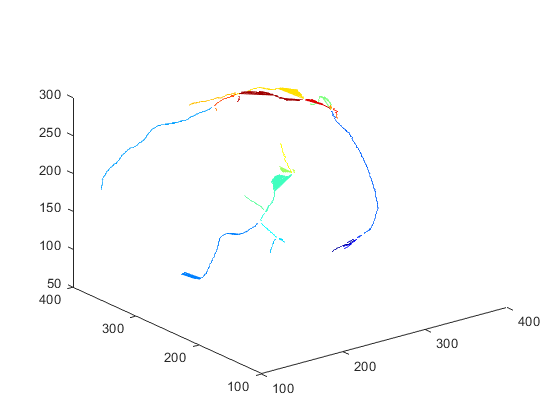

%细化
coro_tree = bwmorph3(DictImg,'fill');
coro_tree = bwskel(coro_tree>0);
stats = regionprops3(coro_tree,'VoxelList','Volume','VoxelIdxList');
VolumeThs = 50;
NumConct = length(stats.Volume);
LenVoxel = stats.Volume;
IndVoxel = stats.VoxelIdxList;
for i = 1:NumConct
    if(LenVoxel(i,1) < VolumeThs)
        coro_tree(IndVoxel{i}) = 0;
        continue;
    end
end
%去除分叉点
BranchPoint = find(bwmorph3(coro_tree, 'branchpoints'));
coro_tree(BranchPoint) = 0;
stats = regionprops3(coro_tree,'VoxelList','Volume','VoxelIdxList');
coronary_show(stats.VoxelList);

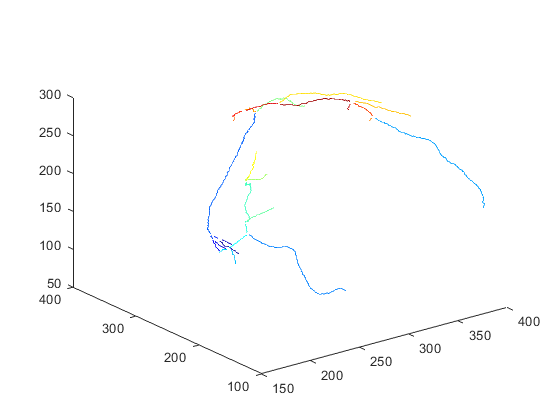


%对每个分支上的点进行排序
BranchNum = length(stats.Volume);
BranchLen = stats.Volume;
BranchVoxelInd = stats.VoxelIdxList; 
BranchEp = find(bwmorph3(coro_tree, 'endpoints'));
CoroTreeSrt = {};
LabelEp = zeros(size(coro_tree));
LabelEp(BranchEp) = 1;
for i = 1:BranchNum
    Ep = find(LabelEp(BranchVoxelInd{i}) == 1);
    if(length(Ep) < 2)
        [subx,suby,subz] = ind2sub(size(coro_tree),stats.VoxelIdxList{i});
        CoroTreeSrt{i} = [subx,suby,subz];
        continue;
    end
    BranchMask = zeros(size(coro_tree));
    BranchMask(BranchVoxelInd{i}) = 1;
    %按照端点，每26邻域一搜索
    Region = BranchVoxelInd{i};
    Start = Region(Ep(1,1));
    End = Region(Ep(2,1));
    [XStart,YStart,ZStart] = ind2sub(size(coro_tree),Start);
    [XEnd,YEnd,ZEnd] = ind2sub(size(coro_tree),End);
    %加一个Mask，即每次只对一个分支进行操作
    %再将下面的coro_tree换成这个Mask
    NewBranch = [XStart,YStart,ZStart];
    BranchMask(XStart,YStart,ZStart) = 0;
    for j = 1:BranchLen(i,1)-1
        MiniVolume = BranchMask(XStart-1:XStart+1,...
        YStart-1:YStart+1,ZStart-1:ZStart+1);
        [dx,dy,dz] = ind2sub(size(MiniVolume),find(MiniVolume == 1));
        Nxyz = [dx,dy,dz] - [2,2,2] + [XStart,YStart,ZStart];
        NewBranch = [NewBranch;Nxyz(1,1),Nxyz(1,2),Nxyz(1,3)];
        BranchMask(Nxyz(1,1),Nxyz(1,2),Nxyz(1,3)) = 0;
        XStart = Nxyz(1,1);
        YStart = Nxyz(1,2);
        ZStart = Nxyz(1,3);
    end
    CoroTreeSrt{i} = NewBranch;
end
CoroTreeSrt = CoroTreeSrt';
coronary_show(CoroTreeSrt);

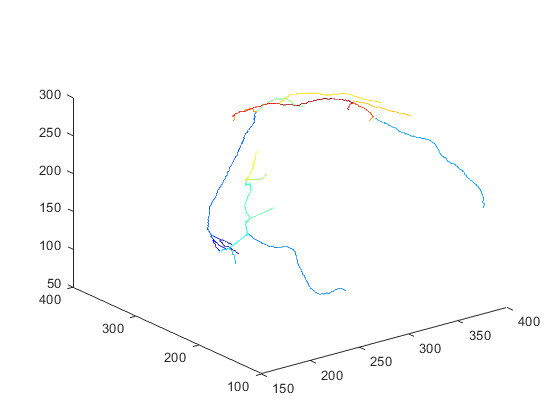


%标定新的连通域
LabelFinal = zeros(size(coro_tree));
for i = 1:length(CoroTreeSrt)
    LabelFinal(CoroTreeSrt{i}(:,1),CoroTreeSrt{i}(:,2),...
    CoroTreeSrt{i}(:,3)) = i;
end


%补充分叉点
CoroTreesSrtUpd = CoroTreeSrt;
[Bp(:,1),Bp(:,2),Bp(:,3)] = ind2sub(size(coro_tree),BranchPoint);
for i = 1:length(BranchPoint)
    MiniVolume = LabelEp(Bp(i,1)-3:Bp(i,1)+3,...
             Bp(i,2)-3:Bp(i,2)+3,Bp(i,3)-3:Bp(i,3)+3);
    [dx,dy,dz] = ind2sub(size(MiniVolume),find(MiniVolume == 1));
    EpCoct = [dx,dy,dz] - [4,4,4] + [Bp(i,1),Bp(i,2),Bp(i,3)];
       EpCoctIdx = sub2ind(size(coro_tree),EpCoct(:,1),EpCoct(:,2),EpCoct(:,3));
    if isempty(EpCoct)
        continue;
    end
    for j = 1 : size(EpCoct,1)
        ConctId = LabelFinal(EpCoct(j,1),EpCoct(j,2),EpCoct(j,3));
        BranchUpd = CoroTreeSrt{ConctId}; 
        BranchUpdIdx = sub2ind(size(coro_tree),BranchUpd(:,1),BranchUpd(:,2),BranchUpd(:,3));
        EpId = find(BranchUpdIdx == EpCoctIdx(j,1));
        if isempty(EpId)
            continue;
        end
        if(EpId == 1)
            BranchUpd = [Bp(i,1),Bp(i,2),Bp(i,3);BranchUpd];
        elseif(EpId == size(BranchUpd,1))
            BranchUpd = [BranchUpd;Bp(i,1),Bp(i,2),Bp(i,3)];            
        end
        CoroTreesSrtUpd{ConctId} = BranchUpd;
        CoroTreeSrt{ConctId} = CoroTreesSrtUpd{ConctId};
    end
end
coronary_show(CoroTreesSrtUpd);